## **Simulation for Active Structures -- A Living Textbook**

**by Yi Zhu (PhD)**

% --- Ensure project source folders are on the MATLAB path -----------------
baseDir = '/Users/aloysius/Documents/serc/optical_reef_jaxson/Sim-FAST';

elementsDir = fullfile(baseDir, '00_SourceCode_Elements');
solverDir   = fullfile(baseDir, '00_SourceCode_Solver');

% Add folders and subfolders (exclude @ and + folder special handling is automatic)
addpath(genpath(elementsDir));
addpath(genpath(solverDir));

% Clear any previously loaded class definitions (helps if you modified files)
clear classes


% Optional: verify MATLAB can find the key classes (prints their locations)
disp('Which for Elements_Nodes:');

Which for Elements_Nodes:


which -all Elements_Nodes

/Users/aloysius/Documents/serc/optical_reef_jaxson/Sim-FAST/00_SourceCode_Elements/@Elements_Nodes/Elements_Nodes.m  % Elements_Nodes constructor



disp('Which for Solver_NR_TrussAction:');

Which for Solver_NR_TrussAction:


which -all Solver_NR_TrussAction

/Users/aloysius/Documents/serc/optical_reef_jaxson/Sim-FAST/00_SourceCode_Solver/@Solver_NR_TrussAction/Solver_NR_TrussAction.m  % Solver_NR_TrussAction constructor



% Optional: savepath if you want these changes to persist across sessions
% Uncomment the next line to save (may require permission):
% savepath;
% --------------

clear all; 
close all; 
clc;

***Please add "00_SourceCode_Elements" and "00_SourceCode_Solver" into path before running the code***

### **Section 02 - Structural Representation and Code Organization**

#### **2.5 Changing the code without going deep into the package!**

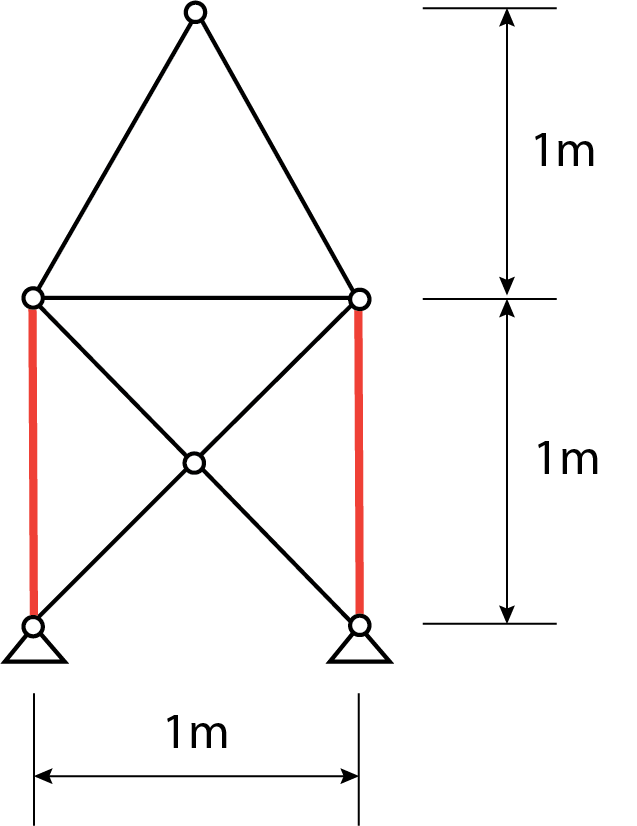

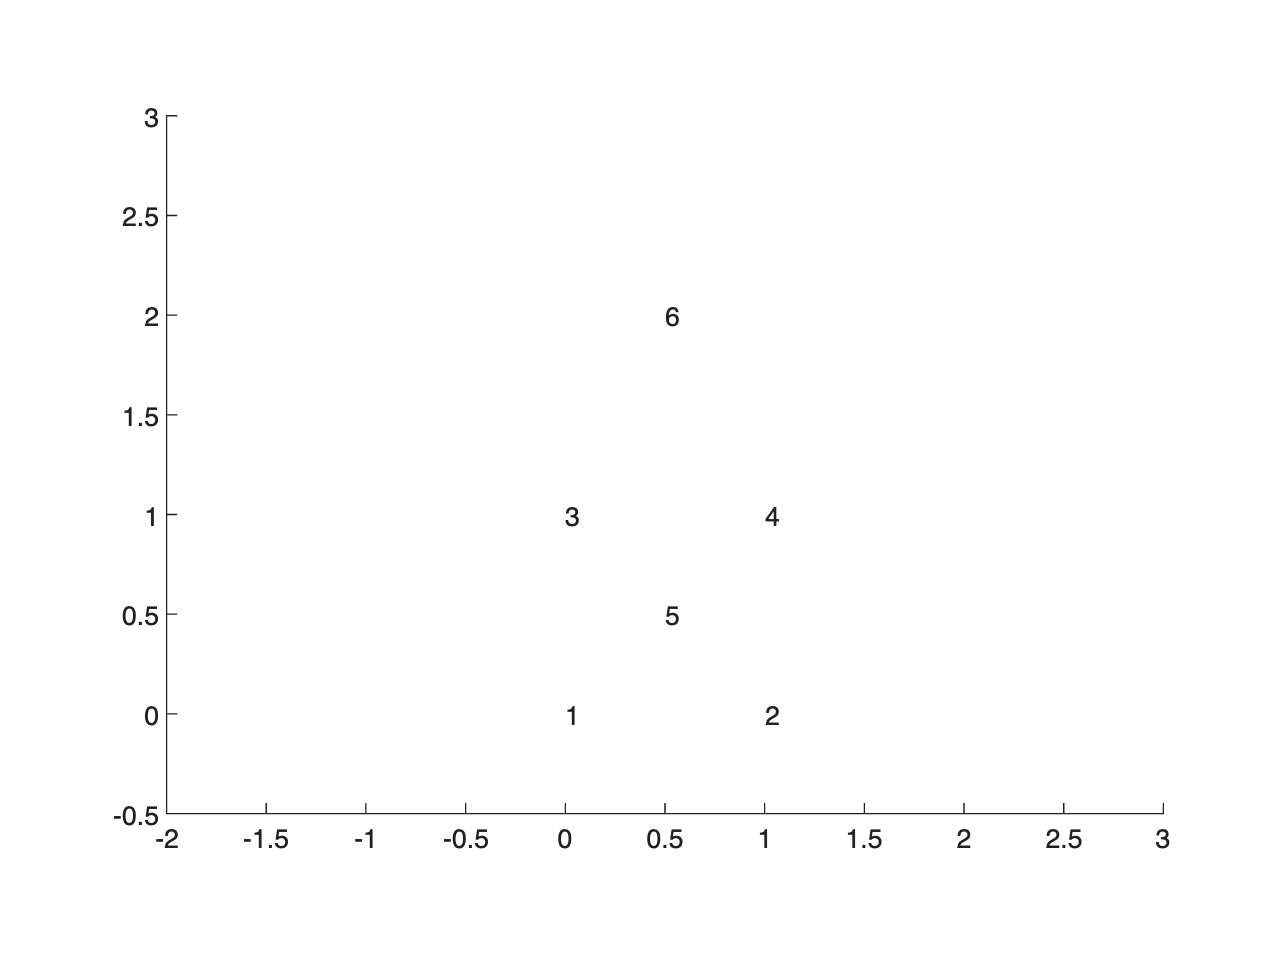

% Create the truss Assembly
assembly=Assembly_Truss;

% Define the node object
node=Elements_Nodes;

% Create the bar object
bar=Vec_Elements_Bars;
actBar=CD_Elements_Bars;

% This assembly has a node object and a bar object
assembly.node=node;
assembly.bar=bar;
assembly.actBar=actBar;

% Define the nodal coordinates
% Length of each span
L=1; 

% Here we need to set up the nodal coordinates of our truss
node.coordinates_mat=[0 0 0; 
                      L 0 0;
                      0 0 L;
                      L 0 L;
                      0.5*L 0 0.5*L;
                      0.5*L 0 2*L;
                      ];

% Set up the plotting function for inspection
plots=Plot_Truss();
plots.assembly=assembly;

% We will plot for the truss assembly
plots.displayRange=[-2;3;-1;1;-0.5;3]; 
plots.viewAngle1=0;
plots.viewAngle2=0;
% Change the viewing angle

% Plot the nodal coordinates for inspection
plots.Plot_Shape_Node_Number()

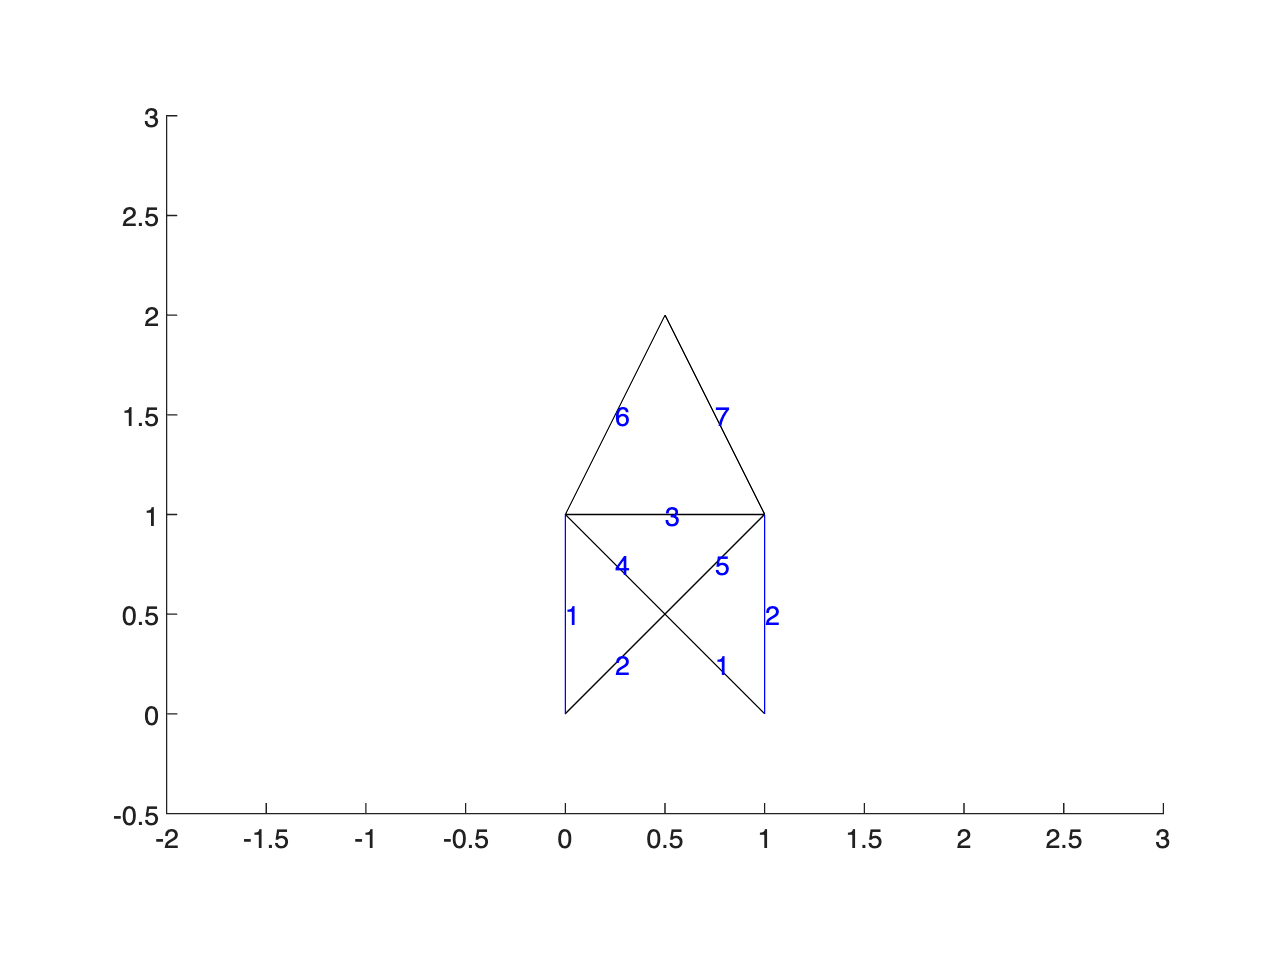

% Define how bars are connected
% First we do the horizontal truss (bars)
bar.node_ij_mat=[2,5;
                 1,5;
                 3,4;
                 3,5;
                 4,5;
                 3,6;
                 4,6;]; 

% Next we design the active truss
actBar.node_ij_mat=[1 3;
                    2 4;];

% Property of normal truss
barA=0.0001; % cross section area (m^2)
barE=2*10^9; % Youngs' modulus (Pa)

% Property of active truss
activeBarE=2*10^6;

% Define the normal bars
bar.A_vec=barA*ones(7,1);
bar.E_vec=barE*ones(7,1);

% Define the active bars
actBar.A_vec=barA*ones(2,1);
actBar.E_vec=activeBarE*ones(2,1);

% Initialize the entire assembly 
assembly.Initialize_Assembly();
% Plot the bars
plots.Plot_Shape_Bar_Number()


% Define the extension and contraction
deltaL=0.3;
% Set up the self actuation solver
nr=Solver_NR_TrussAction;
nr.assembly=assembly;

nr.supp=[1,1,1,1;
         2,1,1,1;
         3,0,1,0;
         4,0,1,0;
         5,0,1,0;
         6,0,1,0;];

% Set up the actuation
nr.targetL0=actBar.L0_vec;

% Find the extention
nr.targetL0(1)=nr.targetL0(1)-deltaL;
nr.targetL0(2)=nr.targetL0(2)+deltaL;

% Set up the total loading step
nr.increStep=10;
% Set up the maximum iteration
nr.iterMax=30;

% Solve for the deformation history
Uhis=nr.Solve();

Self Assemble Analysis StartIcrement = 1
	Iteration = 1, R = 8.496746e+00 
	Iteration = 2, R = 1.374500e+03 
	Iteration = 3, R = 3.678786e+00 
	Iteration = 4, R = 8.188315e-04 
	Iteration = 5, R = 1.501899e-06 
Icrement = 2
	Iteration = 1, R = 8.527450e+00 
	Iteration = 2, R = 1.416708e+03 
	Iteration = 3, R = 3.909685e+00 
	Iteration = 4, R = 3.919354e-01 
	Iteration = 5, R = 8.541785e-04 
	Iteration = 6, R = 2.275184e-08 
Icrement = 3
	Iteration = 1, R = 8.574054e+00 
	Iteration = 2, R = 1.366419e+03 
	Iteration = 3, R = 3.636311e+00 
	Iteration = 4, R = 9.578566e-02 
	Iteration = 5, R = 1.823494e-04 
	Iteration = 6, R = 1.209526e-08 
Icrement = 4
	Iteration = 1, R = 8.637501e+00 
	Iteration = 2, R = 1.368817e+03 
	Iteration = 3, R = 3.652805e+00 
	Iteration = 4, R = 5.609655e-01 
	Iteration = 5, R = 1.243159e-03 
	Iteration = 6, R = 1.186080e-07 
Icrement = 5
	Iteration = 1, R = 8.719210e+00 
	Iteration = 2, R = 1.212723e+03 
	Iteration = 3, R = 2.871716e+00 
	Iteration = 4, R = 4.6

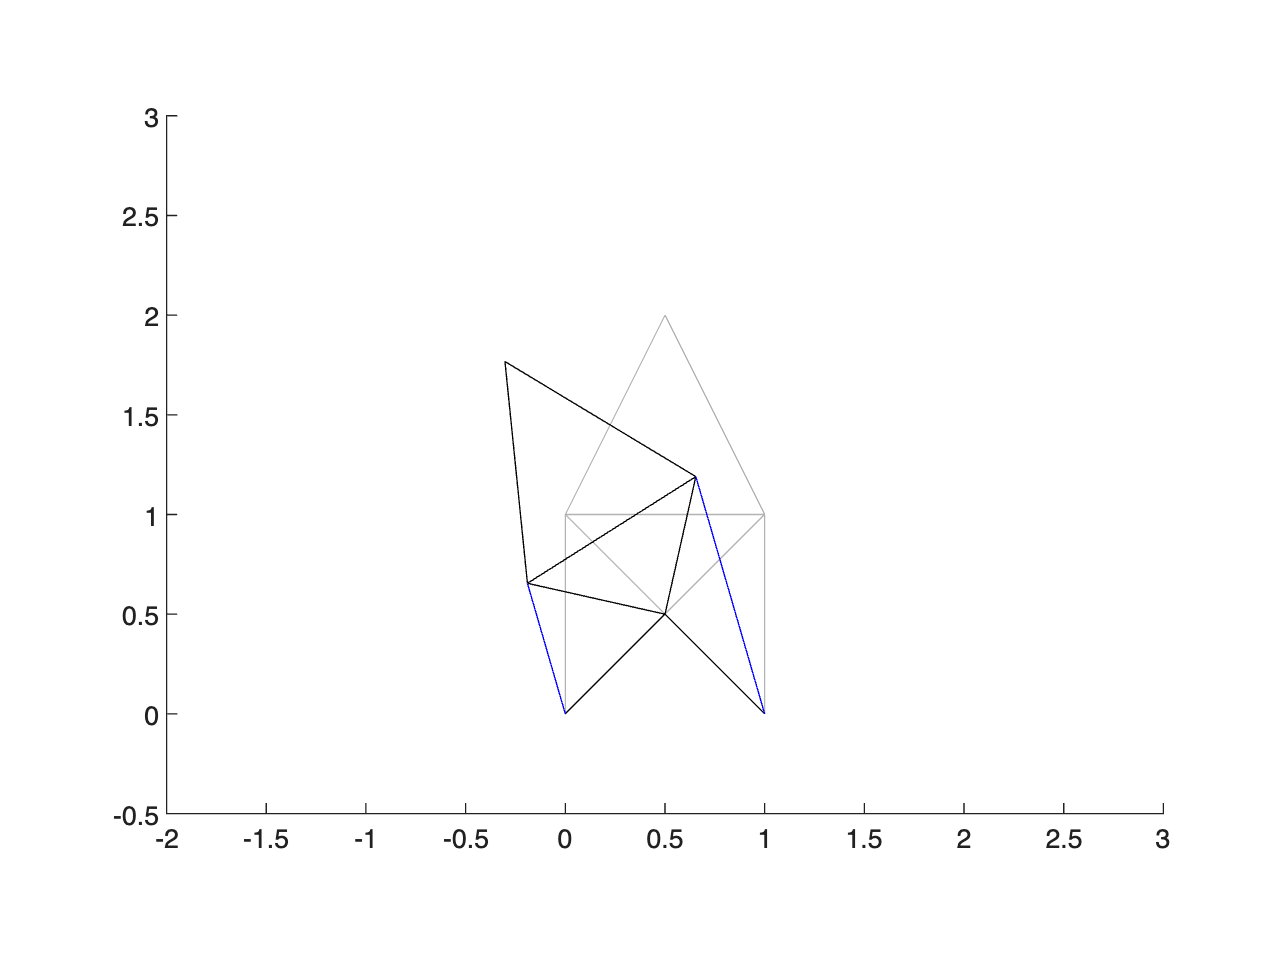

% Plot the deformed shape
plots.Plot_Deformed_Shape(squeeze(Uhis(end,:,:)));